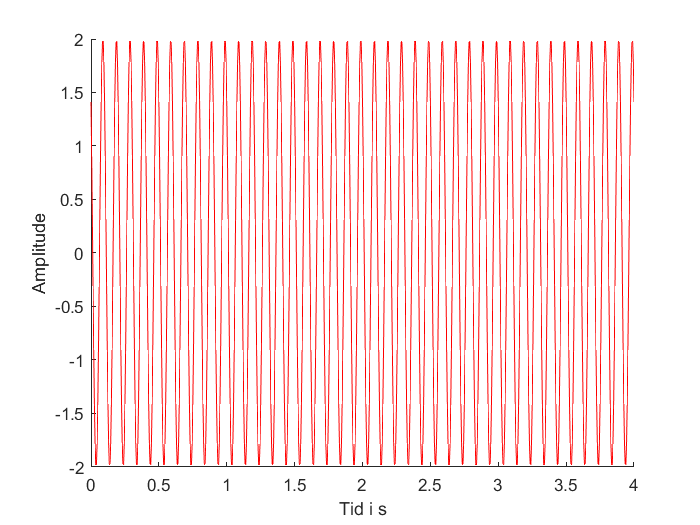

%1.1 Plot a sampled sinusoid over time
%What is the frequency of that signal? 
%What is the phase?

%2*cos(20*pi*t+pi/4)
%Frekvens er 20 radianer pr. tid. 
%Hvis tid er sekunder er frekvensen 3.1831 Hz

%Faseforskydning er pi/4.

%Definere funktion og variable
fs = 200;
dt = 1/fs;
Tstart = 0;
Tslut = 4;
Tvec = Tstart:dt:Tslut;
SinSig = 2*cos(20*pi.*Tvec+pi/4);
figure()
hold on
plot(Tvec,SinSig,'r');
axis([Tstart Tslut -2 2]);
xlabel('Tid i s')
ylabel('Amplitude')


%How can you express the number of samples you get by using the parameters fs and T?
fs*Tslut+1

ans = 801


%Downsample the signal x(n) to sampling frequencies of 10 Hz, 4 Hz, 2 Hz, 1 Hz and
%0.25 Hz by picking the appropriate subset of samples and save them into new vectors
%x 10, x 4, x 2, x 1 and x 025.
names = ["x_10","x_4","x_2","x_1","x_025"];
namesT = ["t_10","t_4","t_2","t_1","t_025"];
fsVec = [10,4,2,1,0.25];
fsVec = 200./fsVec;


for i = 1:length(fsVec)
    name = names{i}; % get the name of the variable
    nameT = namesT{i}
    DownsArray = SinSig(1:fsVec(i):end);
    tArray = Tvec(1:fsVec(i):end);
    assignin('caller',name,DownsArray); % assign the value to the variable in the caller workspace
    assignin('caller',nameT,tArray);
end 

nameT = 't_10'

nameT = 't_4'

nameT = 't_2'

nameT = 't_1'

nameT = 't_025'

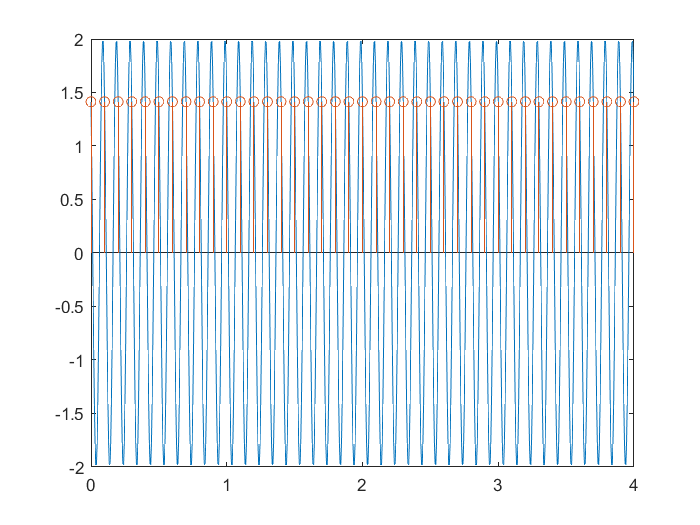


% I provide the first - you do the rest...
figure('Name','fs = 10');
plot(Tvec,SinSig,'-');
hold on;                % this guy will make sure plot into the same figure
stem(t_10, x_10);

set(gca,'xtick',[0:1:Tslut]);   % that is a bit clumsy, but this is how it works!

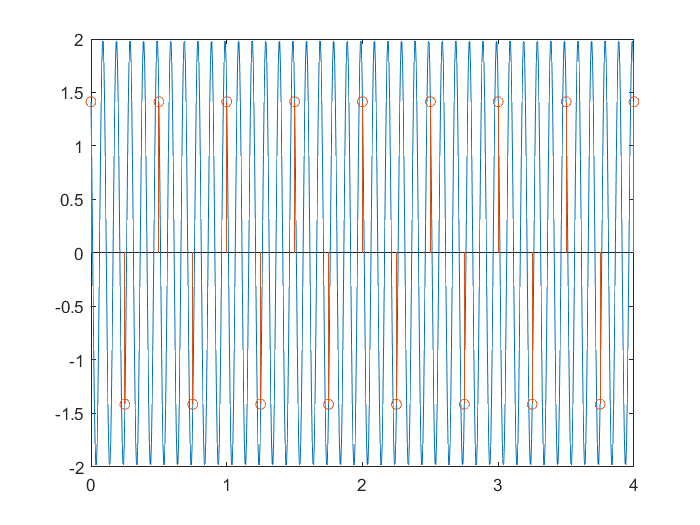



% fs 4
figure('Name','fs = 4');
plot(Tvec,SinSig,'-');
hold on;
stem(t_4,x_4);

set(gca,'xtick',[0:1:Tslut]);

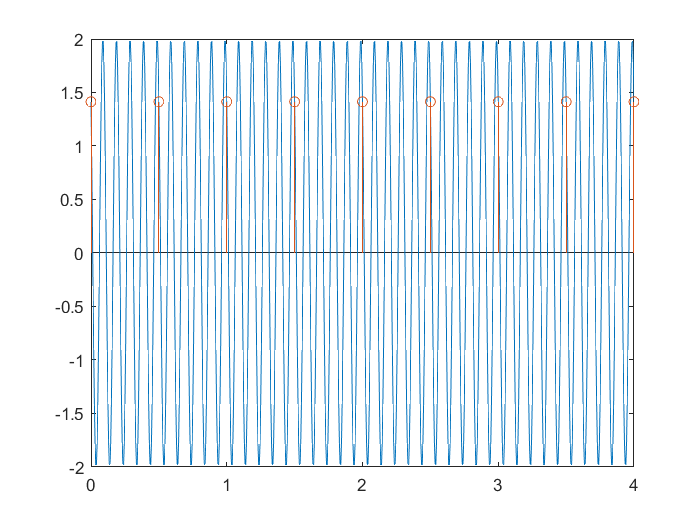

% fs 2
figure('Name','fs = 2');
plot(Tvec,SinSig,'-');
hold on;
stem(t_2,x_2);

set(gca,'xtick',[0:1:Tslut]);

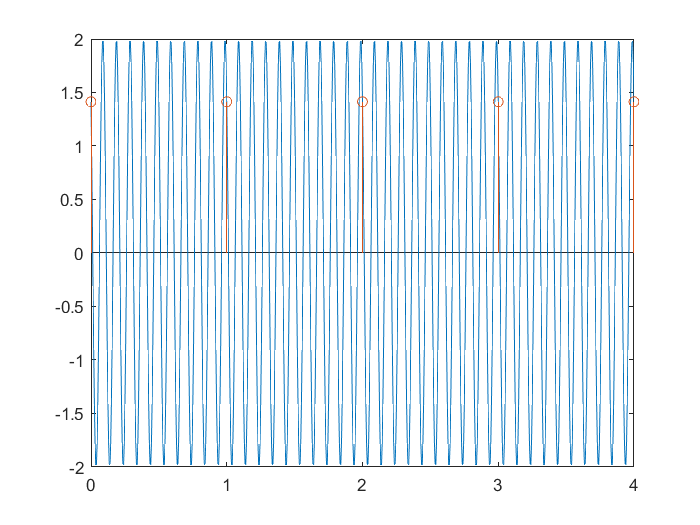


% fs 1
figure('Name','fs = 1');
plot(Tvec,SinSig,'-');
hold on;
stem(t_1,x_1);

set(gca,'xtick',[0:1:Tslut])

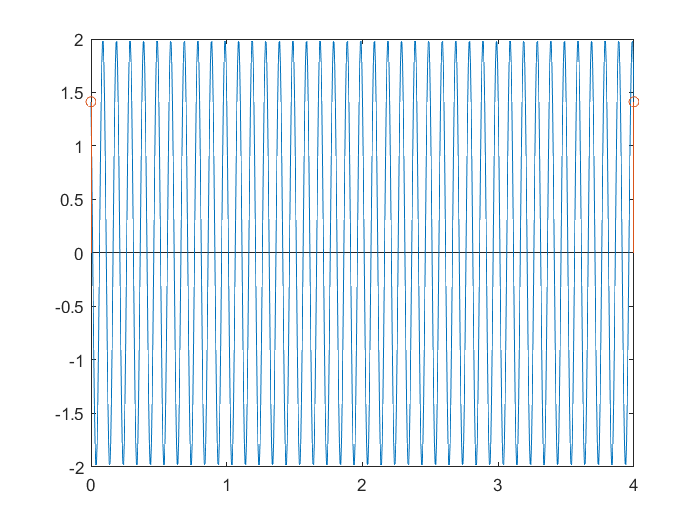


% fs 0.25
figure('Name','fs = 0.25');
plot(Tvec,SinSig,'-');
hold on;
stem(t_025,x_025);

set(gca,'xtick',[0:1:Tslut]);

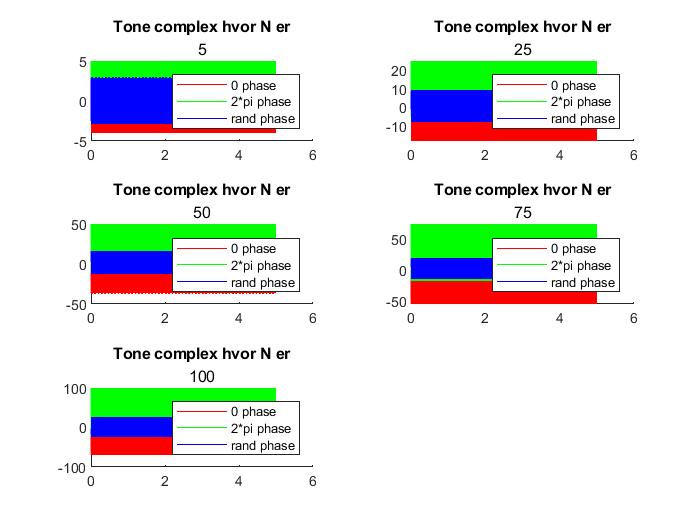

%
% Generate a so-called tone-complex that consists of a sum of
% sinusoids that have integer multiple
% frequencies of each other:

%The sum can be realized in a for-loop. You can use the code written to generate the signal in
%the first part of the hands-on and sum up the single components to the final signal.
%Generate signals (choose values of N between 5 and 100) with equal amplitude ak = 1 ∀k,
%fundamental frequency f0 of 1 kHz at a sampling frequency of 44.1 kHz and duration of 5 s where

clear;
tiledlayout('flow')
for N = [5,25,50,75,100]
ak = 1;
fs = 44.1*10^3;
f_0 = 1*10^3;
dtfs = 1/fs;
dtf_0 = 1/f_0;
TStart = 0;
TSlut = 5;
T = TStart:dtfs:TSlut-dtfs;
%Allokere plads til phase:
phase = zeros(1,N);
%Allokere plads til signal:
Signal = zeros(1,length(T));

%Zero phase signal:
for k=1:N
    Signal = Signal+ak*sin(2*pi*k*f_0.*T+phase(k));
end

%2 Pi phase signal:
Signal2PiPhase = zeros(1,length(T));
phase2Pi = ones(1,N).*pi/2;
for k=1:N
    Signal2PiPhase = Signal2PiPhase+ak*sin(2*pi*k*f_0.*T+phase2Pi(k));
end

%Random phase signal:
phase_r = zeros(1,N);
for i=1:N
phase_r(i) = (2*pi).*rand(1,1);
end
Signal_r = zeros(1,length(T));

for k=1:N
    Signal_r = Signal_r+ak*sin(2*pi*k*f_0.*T+phase_r(k));
end


%Gemmer nulphase
fileName = ['C:\Users\phili\OneDrive\Dokumenter\Signaler og lineære systemer i diskret tid\Hands-on\Sounds\''0phase' num2str(N) 'N.wav'];
audiowrite(fileName,Signal_r,fs,'BitsPerSample',32);

%Gemmer pi/2
fileName = ['C:\Users\phili\OneDrive\Dokumenter\Signaler og lineære systemer i diskret tid\Hands-on\Sounds\''PihalvePhase_' num2str(N) 'N.wav'];
audiowrite(fileName,Signal_r,fs,'BitsPerSample',32);

%Gemmer random
fileName = ['C:\Users\phili\OneDrive\Dokumenter\Signaler og lineære systemer i diskret tid\Hands-on\Sounds\''random_' num2str(N) 'N.wav'];
audiowrite(fileName,Signal_r,fs,'BitsPerSample',32);

nexttile
hold on
plot(T,Signal,'r')
plot(T,Signal2PiPhase,'g')
plot(T,Signal_r,'b')
legend('0 phase','2*pi phase','rand phase')
title('Tone complex hvor N er',num2str(N))
end


%Hvis man lytter til dem er det klart at man kan hører forskel.
path_2_wav = ['C:\Users\phili\Dokumenter\Signaler og lineære systemer i diskret tid\Hands-on', filesep, 'Sounds', filesep];    % the path to the data
fname = ['random_' num2str(25) 'N.wav'];                                 % a file name stored in a string variable

%Nedenunder virker ikke... Bare afspil i stifinderen.
[y, fs_y] = audioread([path_2_wav, fname]);

Error using audioread>readaudio (line 143)
The filename specified was not found in the MATLAB path.

Error in audioread (line 136)
    [y, Fs] = readaudio (filename, range, datatype);